clc; clear; close all;

fid = fopen('my_controller.m', 'w');
fprintf(fid, 'function u = my_controller(e, e_int, yr)\n');
fprintf(fid, '    %%#codegen\n');
fprintf(fid, '    Kp = 1601;\n');
fprintf(fid, '    Ki = 20950;\n');
fprintf(fid, '    Kd = -15000;\n');
fprintf(fid, '    u = Kp * e + Ki * e_int + Kd * yr;\n');
fprintf(fid, 'end\n');
fclose(fid);


disp('Generating C code and MEX function...');

Generating C code and MEX function...


codegen my_controller -args {0.0, 0.0, 0.0} -config:mex -report

Code generation successful: View report



disp('MEX generation completed.');

MEX generation completed.


M = 300; m = 50; D = 1000; k1 = 15000; k2 = 150000;
sys_c = ss([0 0 1 0; 0 0 0 1; -k1/M k1/M -D/M D/M; k1/m -(k1+k2)/m D/m -D/m], ...
           [0 0; 0 0; 1/M 0; -1/m k2/m], [1 0 0 0], 0);

Ts = 0.001; 
sys_d = c2d(sys_c, Ts, 'zoh');
Ad = sys_d.A; Bd = sys_d.B; Cd = sys_d.C;

t = 0:Ts:10;
N = length(t);
R = 0.1 * ones(1, N);
Yr = 0.1 + 0.05*sin(10*t) + 0.02*cos(20*t);

x = zeros(4, 1);
e_int = 0;
U_matlab = zeros(1, N);

for k = 1:N-1
    y = Cd * x;
    e = R(k) - y;
    e_int = e_int + e * Ts; 
    
    
    u = my_controller(e, e_int, Yr(k));
    U_matlab(k) = u;
    x = Ad * x + Bd * [u; Yr(k)];
end

x = zeros(4, 1);
e_int = 0;
U_mex = zeros(1, N);

for k = 1:N-1
    y = Cd * x;
    e = R(k) - y;
    e_int = e_int + e * Ts;
    
    u = my_controller_mex(e, e_int, Yr(k));
    U_mex(k) = u;
    x = Ad * x + Bd * [u; Yr(k)];
end

E_max = max(abs(U_matlab - U_mex));
fprintf('\n======================================================\n');

fprintf('Maximum absolute error (E_max) : %e\n', E_max);

Maximum absolute error (E_max) : 0.000000e+00



if E_max <= 1e-12
    fprintf('SUCCESS: The generated C code is numerically consistent!\n');
else
    fprintf('WARNING: Numerical discrepancy exceeds threshold.\n');
end

SUCCESS: The generated C code is numerically consistent!


fprintf('======================================================\n');

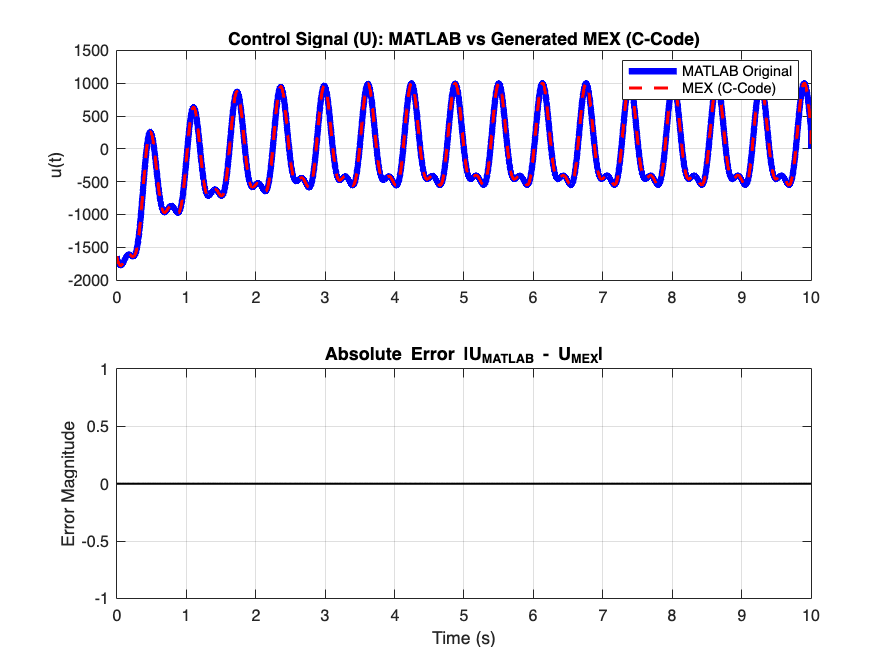

figure('Name', 'Part 6: MEX Verification', 'Color', 'w');
subplot(2,1,1);
plot(t, U_matlab, 'b', 'LineWidth', 4); hold on;
plot(t, U_mex, 'r--', 'LineWidth', 2);
title('Control Signal (U): MATLAB vs Generated MEX (C-Code)');
ylabel('u(t)'); legend('MATLAB Original', 'MEX (C-Code)'); grid on;

subplot(2,1,2);
plot(t, abs(U_matlab - U_mex), 'k', 'LineWidth', 1.5);
title('Absolute Error |U_{MATLAB} - U_{MEX}|');
xlabel('Time (s)'); ylabel('Error Magnitude'); grid on;